# **Sin Wave**

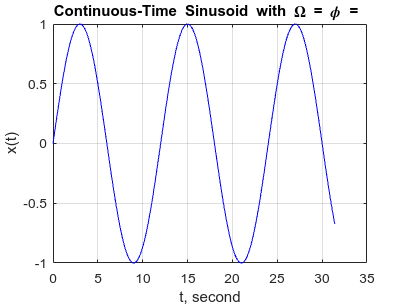

step = 0.01;
nCycles = 5;
Omega = pi/6;
phi = 0;
period = 2*pi/Omega;
n = 0: step: 2*pi*nCycles;
sinusoidCT =  zeros(1,length(n));
sinusoidCT =  sin(Omega*n+phi);
plot(n, sinusoidCT, 'b') 
title('Continuous-Time Sinusoid with \Omega = \phi = ')
xlabel('t, second')
ylabel('x(t)')
grid

# **Triangular Wave**

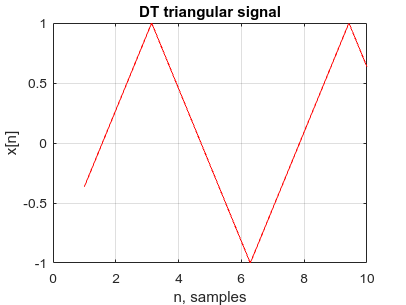

n = 1:step:10;
x = sawtooth(n,1/2);
plot(n, x, 'r')
title('DT triangular signal')
xlabel('n, samples')
ylabel('x[n]')
grid

# **Square Wave**

n = 0:step:10

n =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


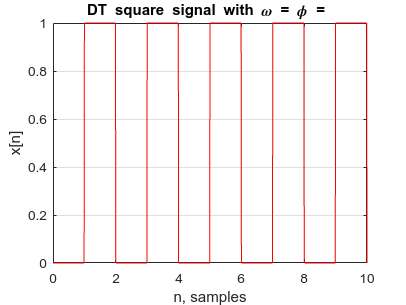

x = zeros(1, length(n));
for i=2:length(n)
    if floor(n(i))==n(i)
        x(i) = 1-x(i-1);
    else
        x(i) = x(i-1);
    end
end
plot(n, x, 'r')
title('DT square signal with \omega = \phi = ')
xlabel('n, samples')
ylabel('x[n]')
grid